M = 4 % Number of Bits per Symbol

M = 4

BAUD_RATE = 1 % Symbols transmitted per second

BAUD_RATE = 1

L = 50 % Number of Symbols to be transmitted

L = 50

SAMPLING_RATE = 20 % Samples per second in Khz

SAMPLING_RATE = 20

Fc = 1 % Carrier Frequency in Khz

Fc = 1

Ac = 1 % Carrier Amplitude

Ac = 1

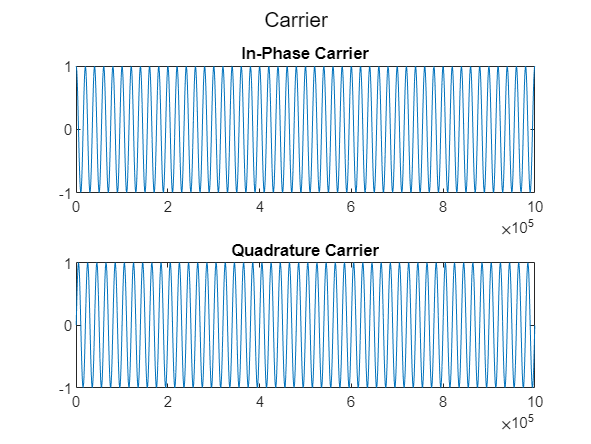


T = L / BAUD_RATE; % tx signal length in seconds
N = SAMPLING_RATE * T * 1000; % Number of samples required
samples_per_symbol = N/L;


n = 0:N-1;
% Carrier Signals
in_phase = Ac*cos(2*pi*Fc*n/N*T);
quadrature = Ac*sin(2*pi*Fc*n/N*T);

figure
subplot(2,1,1)
plot(in_phase)
title("In-Phase Carrier")
subplot(2,1,2)
plot(quadrature)
title("Quadrature Carrier")
sgtitle("Carrier")

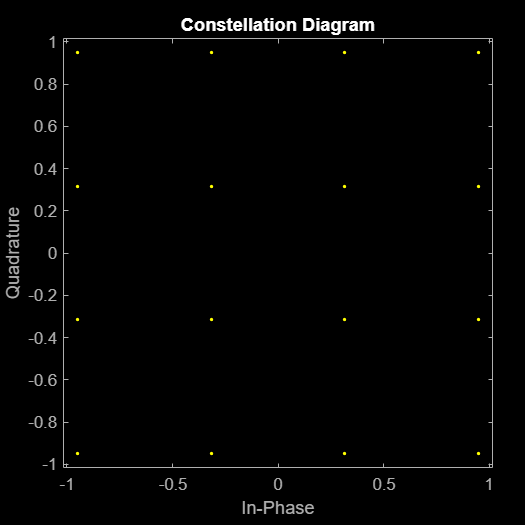



symbols = qammod(0:2^M-1,2^M,"UnitAveragePower",true);

% Generating a random input message signal
message_signal = randi([0 2^M-1],L,1);
encoded_message_signal = zeros(L,1);

tx_signal = zeros(N,1);

for i = 1:L
   encoded_message_signal(i) = symbols(message_signal(i)+1);
   for j = 1:samples_per_symbol
       k = (i-1)*samples_per_symbol + j; % Index of the tx sample
       tx_signal(k) = real(encoded_message_signal(i)) * in_phase(k) + ...
           imag(encoded_message_signal(i)) * quadrature(k); 
   end
end


figure
scatterplot(symbols)
title("Constellation Diagram")

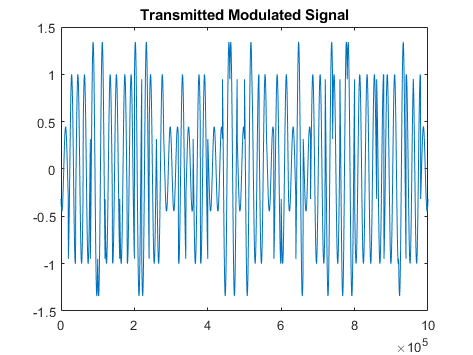


figure
plot(tx_signal)
title("Transmitted Modulated Signal")

% Passing through AWGN Channel

SNR = 25 % Db

SNR = 25

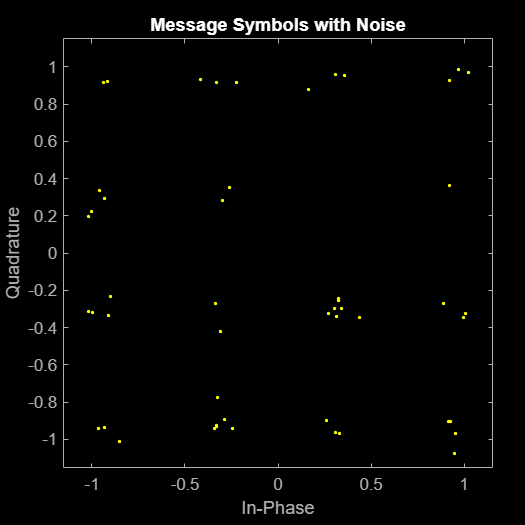

encoded_message_signal_with_noise = AWGN_Custom(encoded_message_signal,SNR);
figure 
scatterplot(encoded_message_signal_with_noise)
title("Message Symbols with Noise")